Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


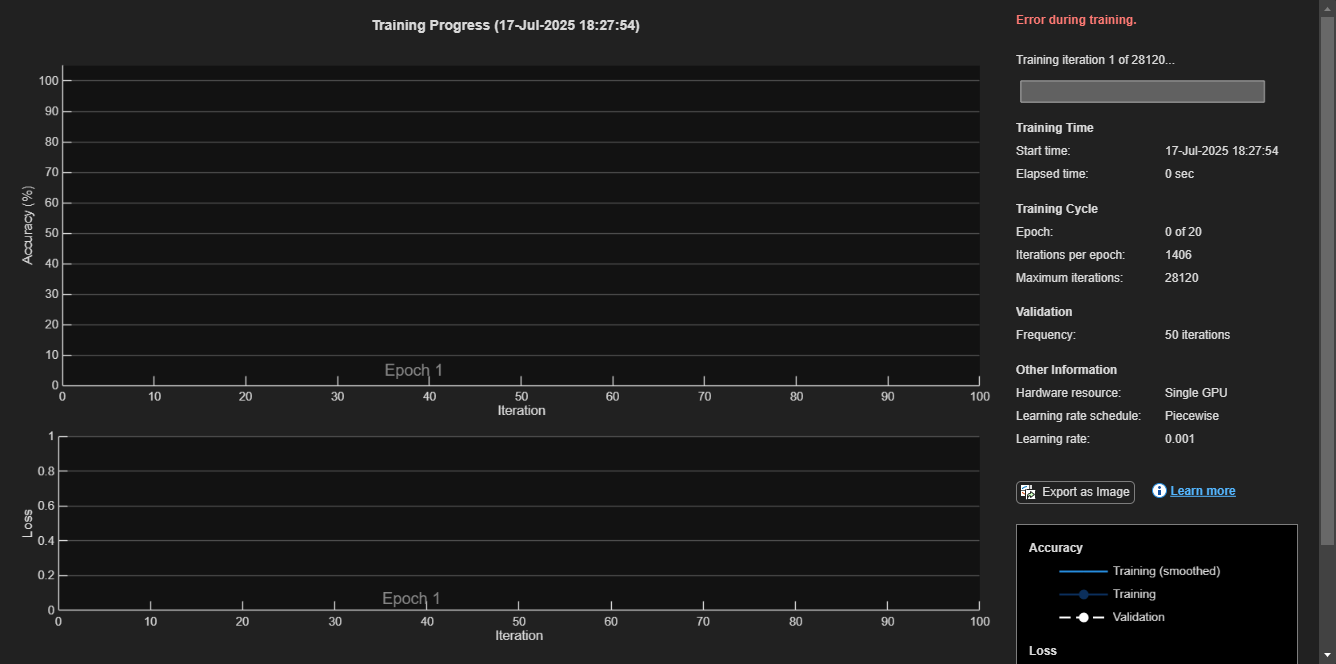

Error using trainNetwork (line 191)
Out of memory.

Caused by:
    Out of memory.

Related documentation

load('trainDataNew90k.mat'); 
load('valDataNew.mat');   

train_labels = categorical(train_labels);
val_labels = categorical(val_labels);

adsXTrain = arrayDatastore(train_dataset, 'IterationDimension', 4);
adsFTrain = arrayDatastore(train_features, 'IterationDimension', 4);
adsYTrain = arrayDatastore(train_labels, 'IterationDimension', 1);
dsTrain = combine(adsXTrain, adsFTrain, adsYTrain);

adsXVal = arrayDatastore(val_dataset, 'IterationDimension', 4);
adsFVal = arrayDatastore(val_features, 'IterationDimension', 4);
adsYVal = arrayDatastore(val_labels, 'IterationDimension', 1);
dsVal = combine(adsXVal, adsFVal, adsYVal);

if ~exist('checkpoints', 'dir')
    mkdir('checkpoints');
end

options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-3, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.3, ...
    'LearnRateDropPeriod', 3, ...
    'L2Regularization', 1e-4, ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 64, ... 
    'Shuffle', 'every-epoch', ...
    'ValidationData', dsVal, ...
    'ValidationFrequency', 50, ...
    'CheckpointPath', 'checkpoints/', ...
    'Verbose', true, ...
    'Plots', 'training-progress');


net = trainNetwork(dsTrain, lgraph, options);

save('trainedModel90k.mat', 'net');


